parameter settings

clear all

P = 3; %4
nGauss = 8; %18
nDelay = 10; %4
GMM_nIter = 10000;

params.sigma = 10;
params.beta = 8/3;
params.rho = 28;
params.eta = sqrt(params.beta*(params.rho-1));

data generation

[t,y] = lorenzgen(params);

Visualize

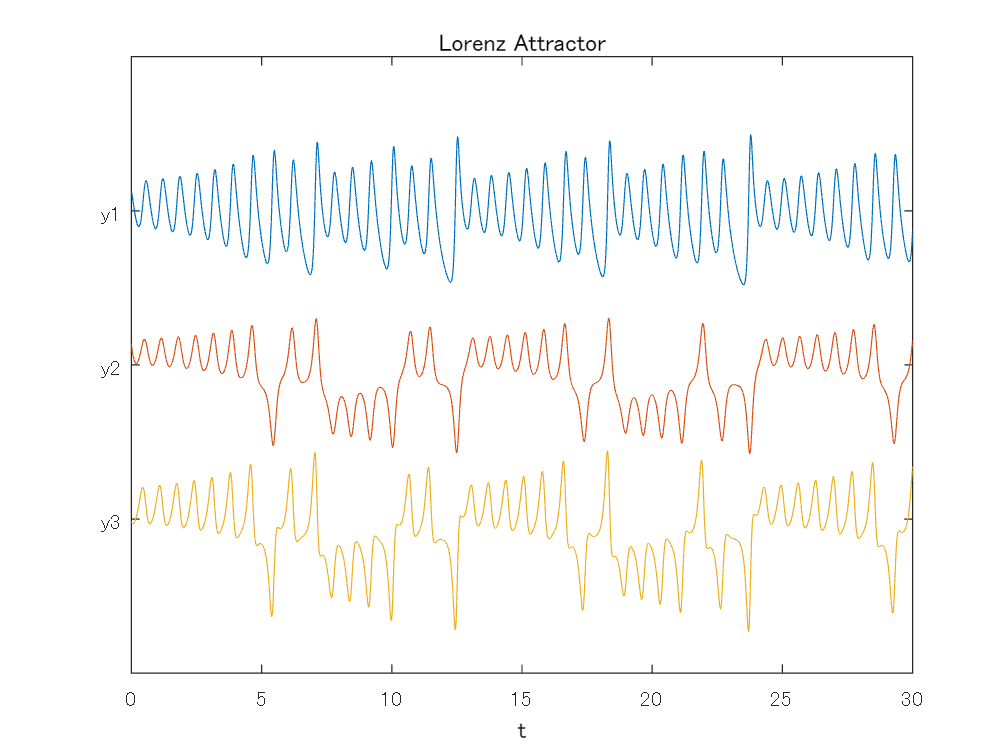

plot(t,[y(:,1)+15 y(:,2)-5 y(:,3)-45]);
axis([0 30 -80 80])
set(gca,'ytick',[-40 0 40],'yticklabel',{'y3','y2','y1'})
xlabel('t')
title('Lorenz Attractor')

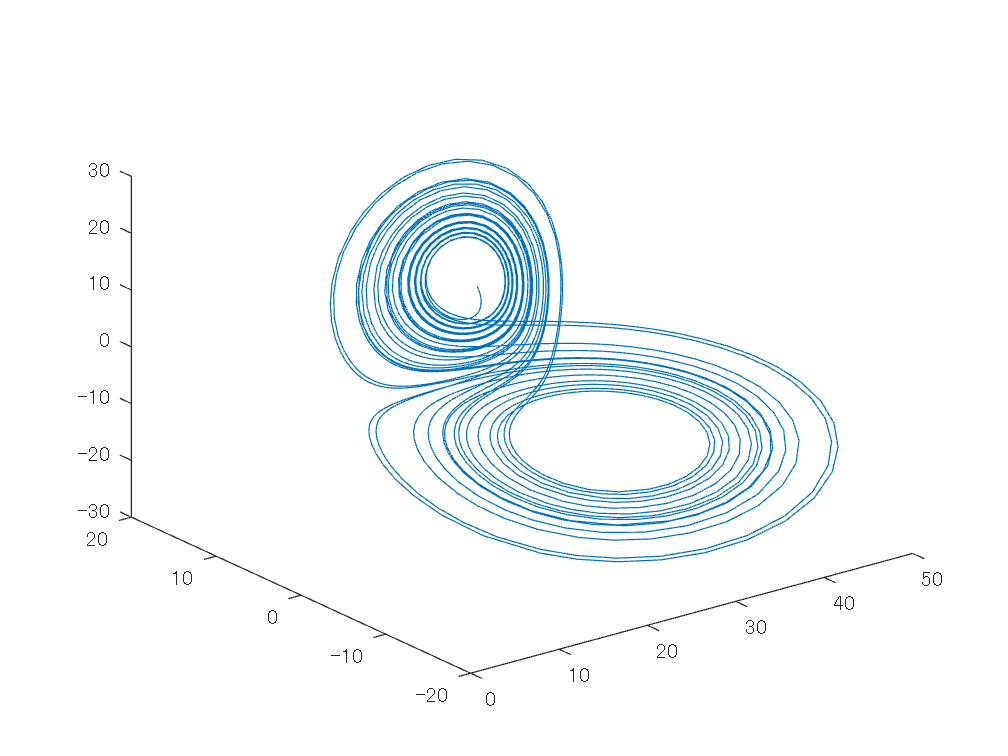


figure
h1 = plot3(y(:,1),y(:,2),y(:,3));

Delayed embedding and data matrix generation

%nDelay = 1;

%ts = [];
%for iCol = 1:size(y,2)
%    c = y(1:nDelay+1,iCol);
%    r = y(nDelay+1:end,iCol);
%    h = hankel(c,r);
%    ts = cat(3,ts,h);
%end

%X = reshape(permute(ts,[2 1 3]),size(ts,2),[]) % Delay 

ts = [];
H = [];
nRange = size(y,1)-1;
for k = 0:nRange-nDelay
    xkT = [];
    for iDelay = 0:nDelay
        xkT = cat(2,xkT,y(k+iDelay+1,:));
    end
    H = cat(2,H,xkT.');
end

X = H.';

Step 1 Clustering

%nGauss = 4;
options = statset('MaxIter',GMM_nIter);

Sigma = 'full';
SharedCovariance = false;

gmfit = fitgmdist(X,nGauss,'CovarianceType',Sigma, ...
    'SharedCovariance',SharedCovariance,'Options',options); % Fit GMM, GMModel = fitgmdist(X,k) returns a Gaussian mixture distribution model (GMModel) with k components fitted to data (X).
clusterX = cluster(gmfit,X); % Cluster index
if nDelay == 0
    hold on
    plot3(gmfit.mu(:,1),gmfit.mu(:,2),gmfit.mu(:,3),'kx','LineWidth',2,'MarkerSize',10)
end
hold off


% figure
% gplotmatrix(X,[],clusterX)

Step 2 Calculate mean vector

acT = gmfit.mu; % Q x 3(d+1)
ac = acT.'; % 3(d+1) x Q

Step 3 PCA (LSUN) design

for c = 1:nGauss
    c
    Sigmac = gmfit.Sigma(:,:,c);
    [PsicT,latent] = pcacov(Sigmac); % <- This was wrong.
    Psi(:,:,c) = PsicT.';
    %Ic = find(clusterX == c);
    %Ic = Ic(1:end-1);
    %
    %X0cT = X(Ic,:);
    %Z0cT = X0cT-acT(c,:); % Mean removed
    %Psi(:,:,c) = pca(Z0cT);
end

c = 1

c = 2

c = 3

c = 4

c = 5

c = 6

c = 7

c = 8

Step 4 

%P = 2; % # of channels
for c = 1:nGauss
    Ic = find(clusterX == c);
    Ic = Ic(1:end-1);
    %
    X0cT = X(Ic,:);
    X1cT = X(Ic+1,:); % Advanced (1 time step)
    Z0cT = X0cT-acT(c,:); % Mean removed
    %
    Psic = Psi(:,:,c); % PCA coeffs (loadings) for the specific cluster
    PsiZ0c = Psi(:,:,c)*Z0cT.'; % (PCAcoeffs) x (Mean removed data) 
    SPsiZ0c = PsiZ0c(1:P,:); % Truncation of channels
    Q_bc = (X1cT).'*pinv([SPsiZ0c; ones(1,size(SPsiZ0c,2))]); % Advanced data x inv(truncated)
    %
    Qc = Q_bc(:,1:end-1); 
    bc(:,c) = Q_bc(:,end);
    %
    Pc_ = Psic(1:P,:)*Qc;
    %
    %[U,S,V] = svd(Pc_);
    Pc(:,:,c) = Pc_; %U*V.';
end

Learnable parameters

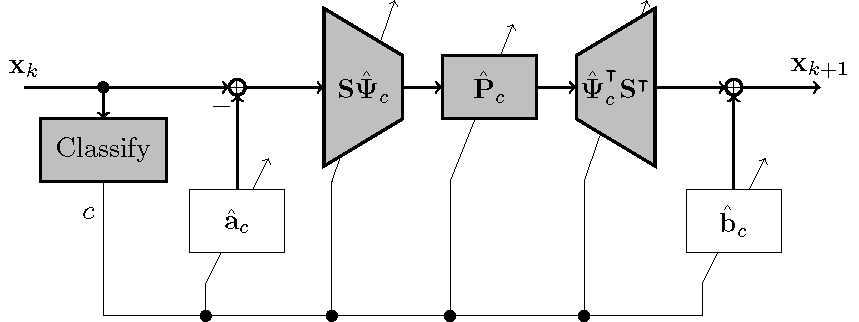


$$\mathbf{S}\hat{\mathbf{\Psi}}_c$$


SPsic = Psi(1:P,:,:)

SPsic = SPsic(:,:,1) =

   -0.0353    0.1253    0.3228    0.0384    0.1512    0.3025    0.1008    0.1688    0.2686    0.1493    0.1781    0.2263    0.1833    0.1799    0.1811    0.2053    0.1761    0.1371    0.2175    0.1676    0.0968    0.2223    0.1559    0.0620    0.2222    0.1422    0.0333    0.2192    0.1275    0.0105    0.2147    0.1124   -0.0074
    0.3079    0.1011   -0.0969    0.2877    0.0772   -0.1432    0.2611    0.0528   -0.1788    0.2325    0.0292   -0.2035    0.2055    0.0075   -0.2193    0.1824   -0.0123   -0.2283    0.1635   -0.0302   -0.2327    0.1486   -0.0467   -0.2346    0.1370   -0.0625   -0.2361    0.1282   -0.0779   -0.2386    0.1208   -0.0937   -0.2429
    0.4304    0.2619    0.1880    0.3558    0.2072    0.0503    0.2393    0.1457   -0.0369    0.1096    0.0892   -0.0703   -0.0098    0.0443   -0.0606   -0.1015    0.0187   -0.0190   -0.1634    0.0121    0.0425   -0.1968    0.0225    0.1131   -0.2089    0.0441    0.1821   -0.2119    0.0705    0.2458   -0.2137    


$$\hat{\mathbf{P}}_c$$


Pc

Pc = Pc(:,:,1) =

    0.9521   -0.0972   -0.1486
    0.1467    0.9801   -0.2450
    0.0630   -0.0497    0.8858


Pc(:,:,2) =

    0.9653    0.2211   -0.2281
   -0.2156    0.9857   -0.0344
    0.0307   -0.0030    0.8356


Pc(:,:,3) =

    0.9839    0.1355   -0.0114
   -0.1944    1.0454   -0.0662
    0.0195    0.0048    0.8223


Pc(:,:,4) =

    1.0330   -0.1798    0.2146
    0.1641    0.9541   -0.2463
   -0.0882    0.0122    0.9621


Pc(:,:,5) =

    1.0447   -0.0146   -0.0981
   -0.0496    0.9590    0.0637
   -0.0529    0.0210    0.8735


Pc(:,:,6) =

    1.1118   -0.0504   -0.1776
   -0.0905    1.0077    0.2532
   -0.0228    0.0043    1.0333


Pc(:,:,7) =

    0.9606    0.1642   -0.0209
   -0.1774    0.9279    0.2675
    0.0083   -0.0075    1.0227


Pc(:,:,8) =

    0.9507    0.1090    0.1458
   -0.1263    1.1118   -0.2340
    0.0114    0.0504    0.8922



$$\hat{\mathbf{a}}_c$$


ac

ac =    34.3325   19.6888   21.3308   13.7471   27.5126   18.1715   31.0694   20.9159
   11.6370    8.4981    4.2555   -3.9690   -0.1608   -0.1416  -11.8697    3.5702
    8.3256   12.7683    5.3956   -6.6158   -0.5527   -0.2993  -11.0003    3.3981
   34.5295   21.1278   20.7492   13.7689   26.4670   17.5477   32.0652   20.1317
   11.0794    9.4132    4.5056   -4.5894   -0.2102   -0.1673  -11.8103    3.5617
    6.9754   13.7746    5.8843   -7.7281   -0.5610   -0.3292  -10.2100    3.7304
   34.4241   22.8355   20.2750   14.0598   25.4533   16.9464   32.8931   19.3959
   10.4119   10.3142    4.8241   -5.3365   -0.2599   -0.1950  -11.6227    3.6238
    5.6751   14.5621    6.4892   -9.0119   -0.5769   -0.3659   -9.2868    4.1449
   34.0419   24.7476   19.9557   14.6412   24.4716   16.3634   33.5420   18.7263



$$\hat{\mathbf{b}}_c$$


bc

bc =    34.5294   21.1255   20.7545   13.7683   26.4680   17.5497   32.0698   20.1327
   11.0798    9.4129    4.5031   -4.5878   -0.2105   -0.1664  -11.8139    3.5613
    6.9711   13.7764    5.8729   -7.7258   -0.5622   -0.3274  -10.2035    3.7322
   34.4231   22.8336   20.2782   14.0572   25.4540   16.9482   32.8946   19.3968
   10.4121   10.3138    4.8203   -5.3342   -0.2603   -0.1939  -11.6251    3.6237
    5.6725   14.5650    6.4765   -9.0095   -0.5776   -0.3643   -9.2810    4.1464
   34.0408   24.7463   19.9554   14.6413   24.4720   16.3652   33.5411   18.7272
    9.6635   11.1508    5.2215   -6.1877   -0.3057   -0.2252  -11.3201    3.7600
    4.4814   15.0455    7.2281  -10.4059   -0.6008   -0.4109   -8.2588    4.6481
   33.4248   26.7649   19.8477   15.5444   23.5321   15.8019   33.9836   18.1423


Classifier

classify = @(x) cluster(gmfit,x.')

classify = 値をもつ function_handle :
    @(x)cluster(gmfit,x.')


simulation

%x0 = rand(6,1);
x0 = X(1,:).';
K = 1728;

% Hard decision
x = x0;
Xhat = x0;
for k = 1:K
    c = classify(x);
    ac_ = ac(:,c);
    bc_ = bc(:,c);
    Pc_ = Pc(:,:,c);
    SPsic_ = SPsic(:,:,c);
    x = SPsic_.'*Pc_*SPsic_*(x-ac_) + bc_;
    Xhat = [Xhat x];
end
Xhat

Xhat = 1.0e+31 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000 

%

yhat = Xhat(1:nDelay+1:end,:).' % <- This was wrong.

yhat = 1.0e+31 *

    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000


that = t(1:K+1)

that =          0
    0.0088
    0.0176
    0.0263
    0.0351
    0.0561
    0.0772
    0.0982
    0.1192
    0.1437


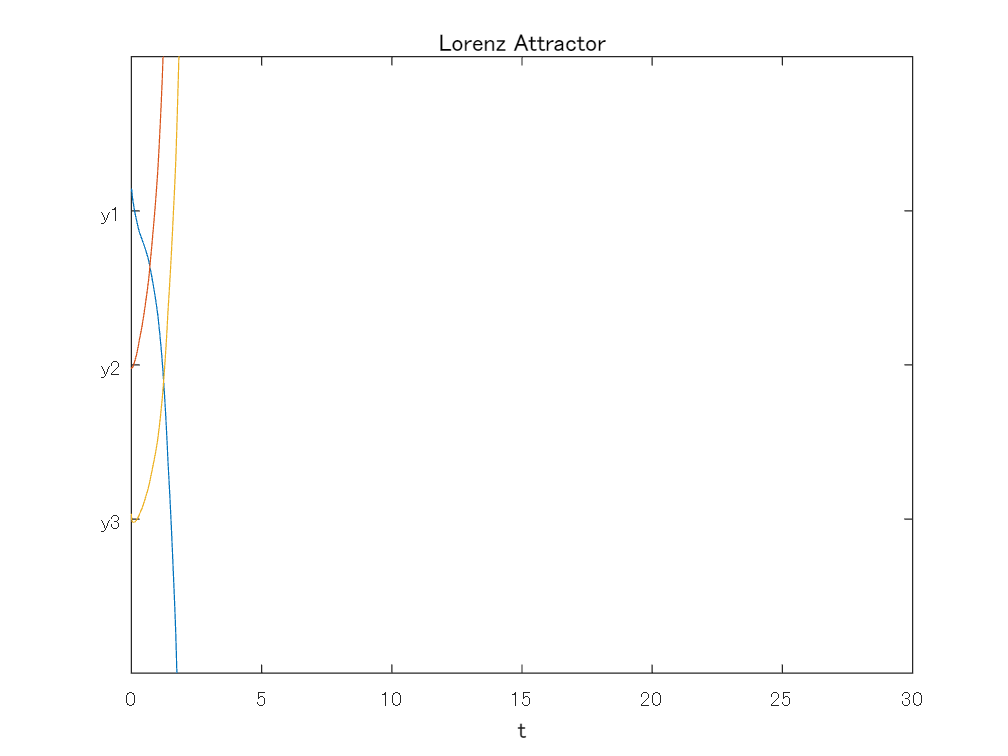

plot(that,[yhat(:,1)+15 yhat(:,2)-5 yhat(:,3)-45]);
axis([0 30 -80 80])
set(gca,'ytick',[-40 0 40],'yticklabel',{'y3','y2','y1'})
xlabel('t')
title('Lorenz Attractor')

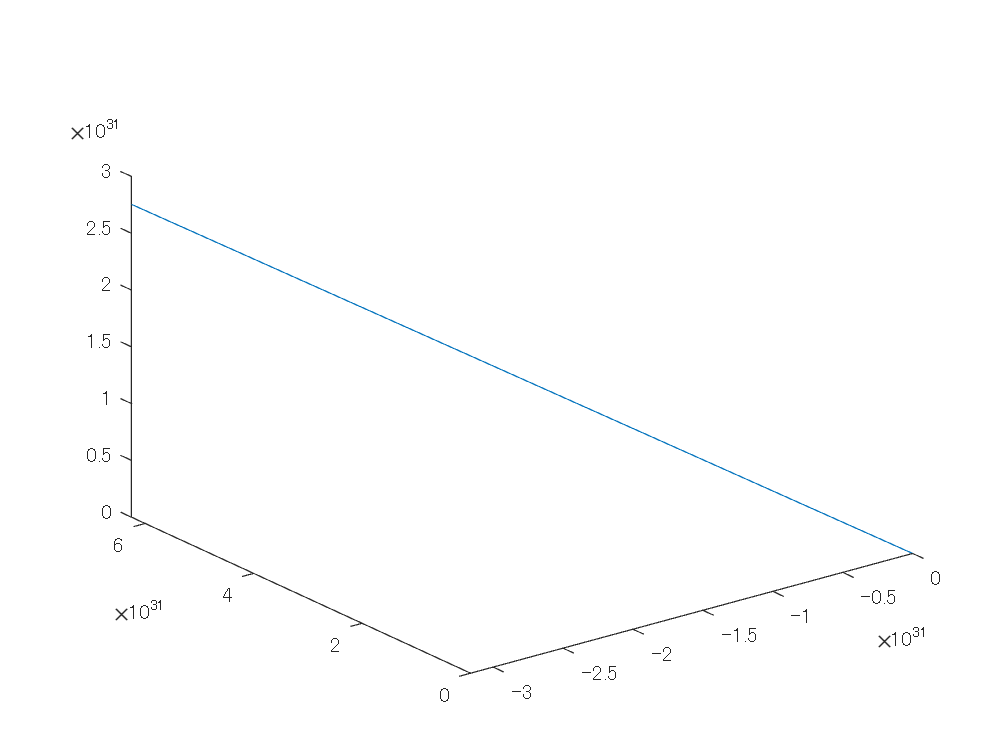

figure
h2 = plot3(yhat(:,1),yhat(:,2),yhat(:,3));

x0 = X(1,:).';
weightin = @(x) posterior(gmfit,x.')

weightin = 値をもつ function_handle :
    @(x)posterior(gmfit,x.')


% Soft decition
%x0 = rand(6,1);
x = x0;
Xhat = x0;
for k = 1:K
    w = weightin(x); 
    %w = posterior(gmfit,x.;);
    x_ = 0;
    for c = 1:nGauss % TODO: to process in parallel
        ac_ = ac(:,c);
        bc_ = bc(:,c);
        Pc_ = Pc(:,:,c);
        SPsic_ = SPsic(:,:,c);
        x_ = x_ + w(c) * (SPsic_.'*Pc_*SPsic_*(x-ac_) + bc_);
        %x_s(:,c) = x_;
    end
    %x_s = x;
    x = x_;
    Xhat = [Xhat x];
end
Xhat

Xhat = 1.0e+31 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000 


%Visualize
yhat = Xhat(1:nDelay+1:end,:).'

yhat = 1.0e+31 *

    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000


that = t(1:K+1)

that =          0
    0.0088
    0.0176
    0.0263
    0.0351
    0.0561
    0.0772
    0.0982
    0.1192
    0.1437


plot(that,[yhat(:,1)+15 yhat(:,2)-5 yhat(:,3)-45]);
axis([0 30 -80 80])
set(gca,'ytick',[-40 0 40],'yticklabel',{'y3','y2','y1'})
xlabel('t')
title('Lorenz Attractor')

figure
h3 = plot3(yhat(:,1),yhat(:,2),yhat(:,3));

function [t,y] = lorenzgen(params)

sigma = params.sigma;
beta = params.beta;
rho = params.rho;
eta = params.eta;

A = [ -beta 0 eta;
    0 -sigma sigma;
    -eta rho -1 ];
v0 = [rho-1 eta eta]';
y0 = v0 + [3 2 -4]';
tspan = [0 30];

[t,y] = ode45(@(t,y) lorenzeqn(t,y,A), tspan, y0);
end

function ydot = lorenzeqn(t,y,A)

A(1,3) = y(2);
A(3,1) = -y(2);
ydot = A*y;

end